close all;
clear all;

clock_freq = 1e8;
limits = [1, 2, 3, 4, 5, 6, 7, 8, 9, 10, 11, 12, 13, 14, 15, 16, 17, 18, 19, 20, 22, 24, 26, 28, 30, 35, 45, 60, 75, 100, 125, 150, 175, 200];


## RO

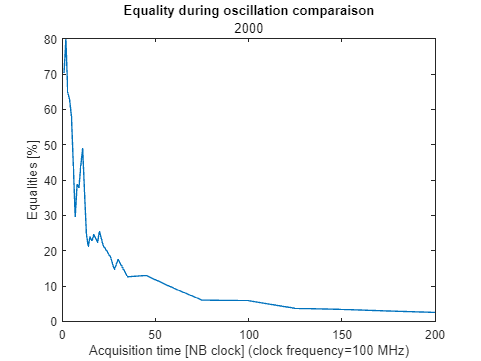

prefix = "ro_raw_equality";

equalities_ro = zeros(1, length(limits));
data = readmatrix(prefix+'_'+string(limits(1))+'.csv');
[size_sample_ro, size_response_ro] = size(data);

for i=1:length(limits)
    data = readmatrix(prefix+'_'+string(limits(i))+'.csv');
    equalities_ro(i) = mean(sum(data,2)/size_response_ro)*100;
end

figure;
plot(limits, equalities_ro);
title("Equality during oscillation comparaison");
xlabel("Acquisition time [NB clock] (clock frequency="+string(clock_freq/1e6)+" MHz)");
ylabel("Equalities [%]");
subtitle(string(size_sample_ro));

## TERO-4

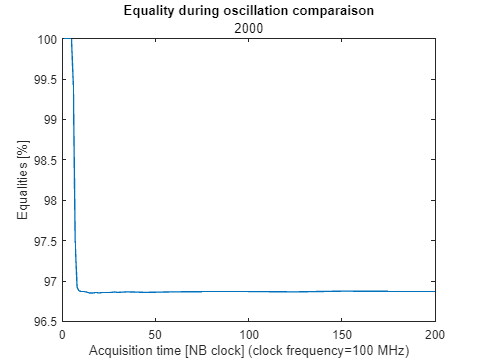

prefix = "tero_4_raw_equality";

equalities_tero_4 = zeros(1, length(limits));
data = readmatrix(prefix+'_'+string(limits(1))+'.csv');
[size_sample_tero_4, size_response_tero_4] = size(data);

for i=1:length(limits)
    data = readmatrix(prefix+'_'+string(limits(i))+'.csv');
    equalities_tero_4(i) = mean(sum(data,2)/size_response_tero_4)*100;
end

figure;
plot(limits, equalities_tero_4);
title("Equality during oscillation comparaison");
xlabel("Acquisition time [NB clock] (clock frequency="+string(clock_freq/1e6)+" MHz)");
ylabel("Equalities [%]");
subtitle(string(size_sample_tero_4));

## TERO-8

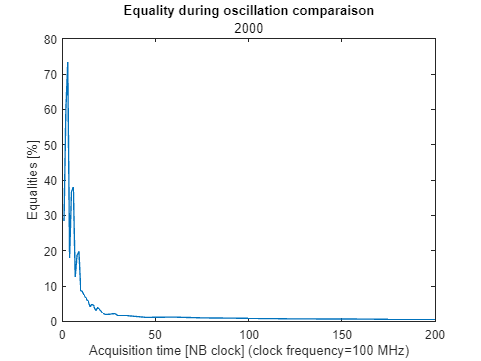

prefix = "tero_8_raw_equality";

equalities_tero_8 = zeros(1, length(limits));
data = readmatrix(prefix+'_'+string(limits(1))+'.csv');
[size_sample_tero_8, size_response_tero_8] = size(data);

for i=1:length(limits)
    data = readmatrix(prefix+'_'+string(limits(i))+'.csv');
    equalities_tero_8(i) = mean(sum(data,2)/size_response_tero_8)*100;
end

figure;
plot(limits, equalities_tero_8);
title("Equality during oscillation comparaison");
xlabel("Acquisition time [NB clock] (clock frequency="+string(clock_freq/1e6)+" MHz)");
ylabel("Equalities [%]");
subtitle(string(size_sample_tero_8));

## ALL

figure;
plot(limits, equalities_ro);
hold on;
plot(limits, equalities_tero_4);
hold on;
plot(limits, equalities_tero_8);
title("Equality during oscillation comparaison");
xlabel("Acquisition time [NB clock] (clock frequency="+string(clock_freq/1e6)+" MHz)");
ylabel("Equalities [%]");
legend("RO","TERO-4","TERO-8");